Here is a matrix with both lower and upper bandwidth equal to one. Such a matrix is called **tridiagonal**. The `spdiags` command creates a sparse matrix given its diagonal elements. The ``main'' or central diagonal is numbered zero, above and to the right of that is positive, and below and to the left is negative.

n = 50;
d = [ n*ones(n,1), ones(n,1), -(1:n)'];  % diagonal entries
pos = [-3 0 1];                          % which diagonals
A = spdiags(d,pos,n,n);
full( A(1:7,1:7) )

ans =      1    -2     0     0     0     0     0
     0     1    -3     0     0     0     0
     0     0     1    -4     0     0     0
    50     0     0     1    -5     0     0
     0    50     0     0     1    -6     0
     0     0    50     0     0     1    -7
     0     0     0    50     0     0     1


Without pivoting, the LU factors have the same lower and upper bandwidth as the orignal matrix. 

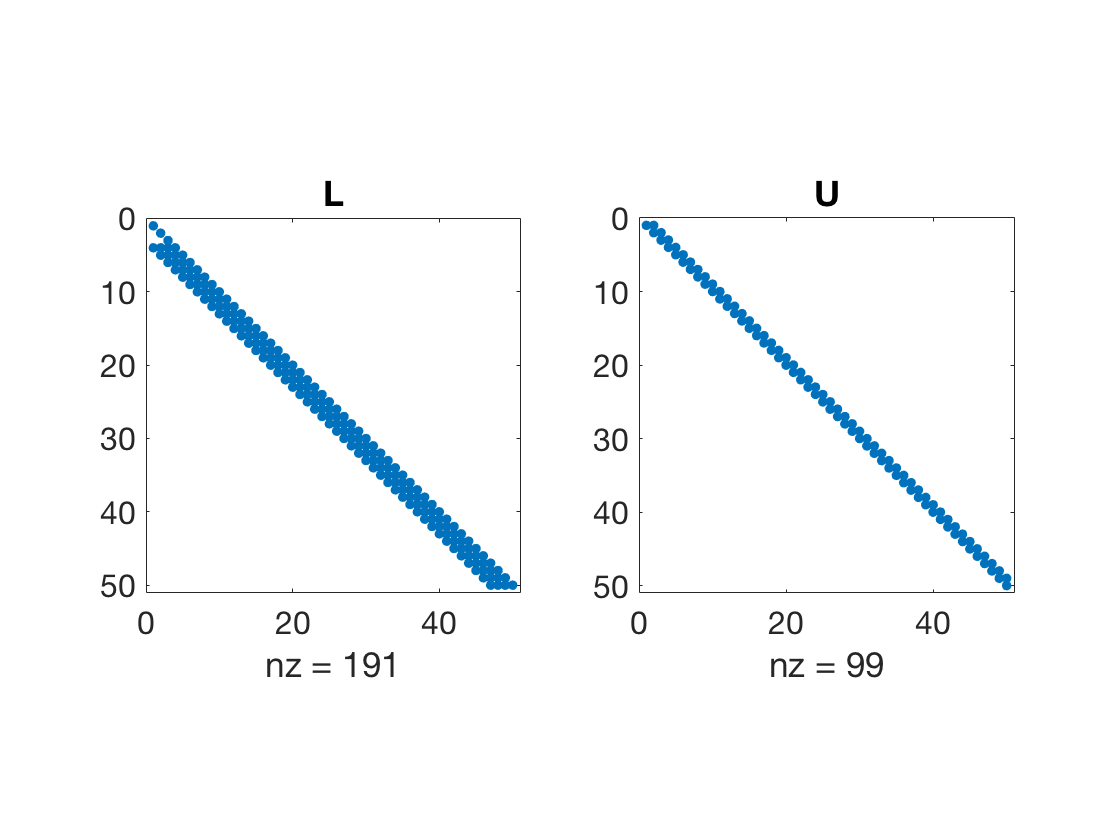

[L,U] = lufact(A);
subplot(1,2,1), spy(L), title('L')
subplot(1,2,2), spy(U), title('U')

However, if we introduce row pivoting, bandedness may be expanded or destroyed.

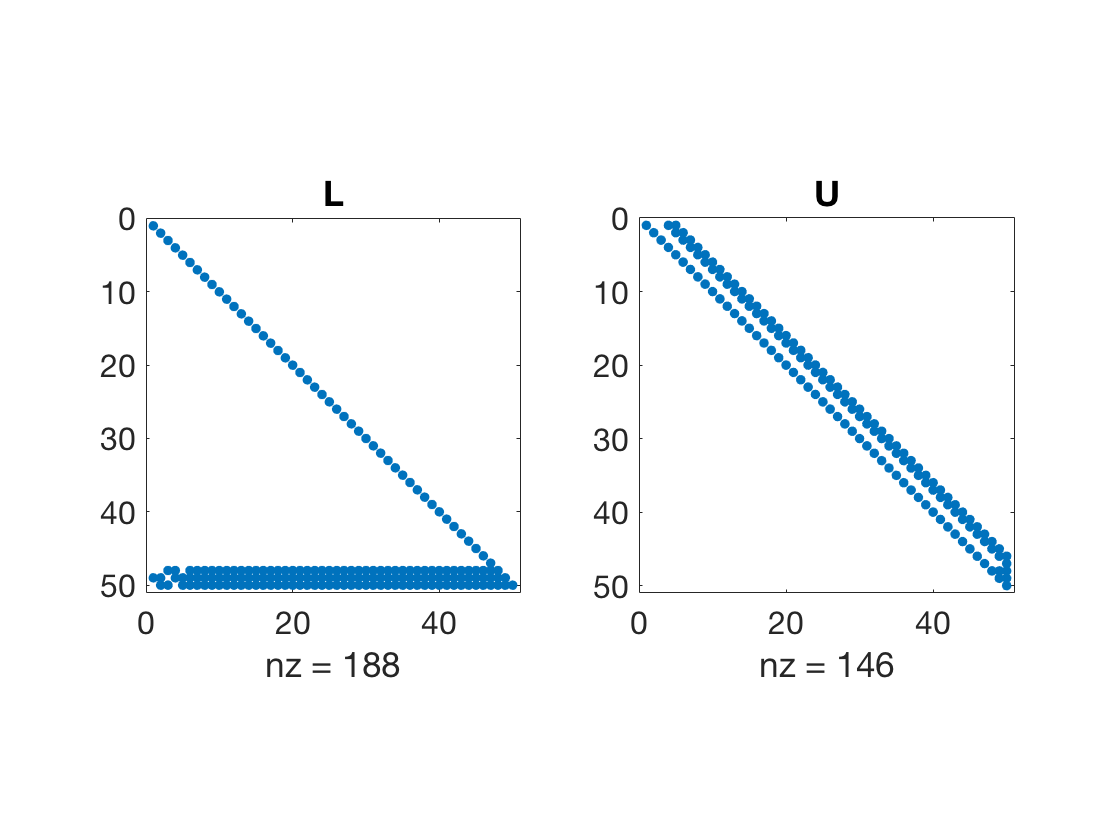

[L,U,P] = lu(A);
subplot(1,2,1), spy(L), title('L')
subplot(1,2,2), spy(U), title('U')